## A03 - MMc

clear all;
close all;
clc;

format short;

Consider a system modelled with an *M/M/c* queue, with the service demand reported below. Consider the system under different workloads according to the minimum and maximum values reported below. In particular, consider 51 equally spaced arrival rates between the two values. Consider also different configurations, varying the number of servers from $c=1$ to $c=8$


$$D = 2\\
\lambda_{min} = 1\\
\lambda_{max} = 10\\
R_{th} = 3$$


where $R_{th}$ is the response time threshold.

D = 2;
Lmin = 1;
Lmax = 10;
Rth = 3;

Let's compute the 51 intervals for $\lambda$:

L = (Lmin:(Lmax-Lmin)/50:Lmax)

L =     1.0000    1.1800    1.3600    1.5400    1.7200    1.9000    2.0800    2.2600    2.4400    2.6200    2.8000    2.9800    3.1600    3.3400    3.5200    3.7000    3.8800    4.0600    4.2400    4.4200    4.6000    4.7800    4.9600    5.1400    5.3200    5.5000    5.6800    5.8600    6.0400    6.2200    6.4000    6.5800    6.7600    6.9400    7.1200    7.3000    7.4800    7.6600    7.8400    8.0200    8.2000    8.3800    8.5600    8.7400    8.9200    9.1000    9.2800    9.4600    9.6400    9.8200


c = (1:8)

c =      1     2     3     4     5     6     7     8


For each arrival rate/number of servers couple determine:

### a. If the system is stable

In order to be stable, a system must have $\overline{U} < 1$, with $\overline{U} = \frac{\lambda \times D}{c} = \rho$

Ubar_fun = @(l,c) (l.*D)./c;

Ubar = zeros(length(L), length(c));

for i = 1:length(L)
    for j = 1:length(c)
        Ubar(i,j) = Ubar_fun(L(i), c(j));
    end
end

UbarT = array2table(Ubar, ...
    'RowNames',strtrim(cellstr(num2str(L'))'), ...
    'VariableNames',strtrim(cellstr(num2str(c'))'))

UbarT = 51×8 table
             1       2         3        4        5         6          7         8  
            ____    ____    _______    ____    _____    _______    _______    _____

    1          2       1    0.66667     0.5      0.4    0.33333    0.28571     0.25
    1.18    2.36    1.18    0.78667    0.59    0.472    0.39333    0.33714    0.295
    1.36    2.72    1.36    0.90667    0.68    0.544    0.45333    0.38857     0.34
    1.54    3.08    1.54     1.0267    0.77    0.616    0.51333       0.44    0.385
    1.72    3.44    1.72     1.1467    0.86    0.688    0.57333    0.49143     0.43
    1.9      3.8  

Let's plot the $\overline{U}$ results in a heatmap:

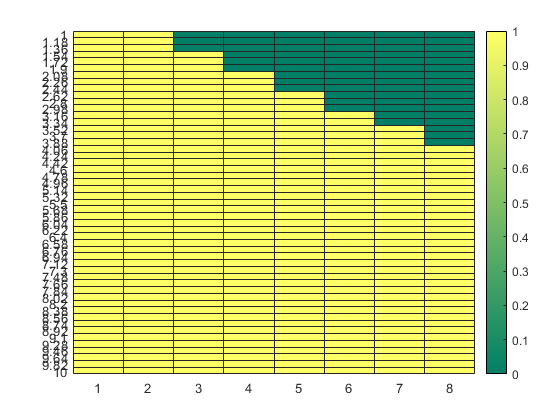

hm = heatmap(strtrim(cellstr(num2str(c'))'), ...
        strtrim(cellstr(num2str(L'))'), ...
        double(Ubar>=1), ...
        'Colormap', summer);

### c. The average time spent in the queue (if possible)

We know that we can compute the average time spent in the queue if the system is stable.


$$\Theta = \frac{\frac{D}{c(1-\rho)}}{1 + (1-\rho) \left(\frac{c!}{(c\rho)^c}\right) \sum_{k=0}^{c-1} \frac{(c\rho)^k}{k!}}$$


theta = @(C,p,D,k) D / (C*(1-p)) / (1 + (1-p)*(factorial(C)/((C*p)^C))*sum(((C*p).^k)./factorial(k)));

Theta = zeros(length(L), length(c));

for i = 1:length(L)
    for j = 1:length(c)
        if Ubar(i,j) < 1
            rho = Ubar(i,j);
            k = 0:c(j)-1;
            
            Theta(i,j) = theta(c(j), rho, D, k);
        end 
    end
end

ThetaT = array2table(Theta, ...
    'RowNames',strtrim(cellstr(num2str(L'))'), ...
    'VariableNames',strtrim(cellstr(num2str(c'))'))

ThetaT = 51×8 table
            1    2       3          4          5           6            7            8     
            _    _    _______    _______    ________    ________    _________    __________

    1       0    0    0.88889    0.17391    0.039801    0.009009    0.0019242    0.00038188
    1.18    0    0     1.9551    0.33465    0.081173    0.020438    0.0049629     0.0011333
    1.36    0    0     5.9205    0.62212      0.1513    0.040941     0.010978     0.0028079
    1.54    0    0          0     1.1815     0.26711    0.075207     0.021734     0.0060938
    1.72    0    0          0     2.5306     0.46022     0.13013     0

### b. The average response time $R$ of the system (if possible)

From the theory we know that $R = D + \Theta$ so we only need to add D to the $\Theta$

R = (Theta + D).*double(Ubar<1);
RT = array2table(R, ...
    'RowNames',strtrim(cellstr(num2str(L'))'), ...
    'VariableNames',strtrim(cellstr(num2str(c'))'))

RT = 51×8 table
            1    2      3         4         5         6         7         8   
            _    _    ______    ______    ______    ______    ______    ______

    1       0    0    2.8889    2.1739    2.0398     2.009    2.0019    2.0004
    1.18    0    0    3.9551    2.3347    2.0812    2.0204     2.005    2.0011
    1.36    0    0    7.9205    2.6221    2.1513    2.0409     2.011    2.0028
    1.54    0    0         0    3.1815    2.2671    2.0752    2.0217    2.0061
    1.72    0    0         0    4.5306    2.4602    2.1301    2.0396     2.012
    1.9     0    0         0    10.914    2.7993    2.21

Let's plot the response time

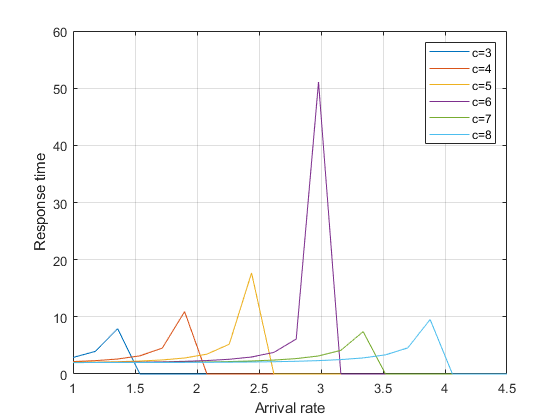

plot(L',[R(:,3),R(:,4),R(:,5),R(:,6),R(:,7),R(:,8)]);
xlabel("Arrival rate");
ylabel("Response time");
legend(["c=3", "c=4", "c=5", "c=6", "c=7", "c=8"]);
xlim([1, 4.5]);
grid on;
hold off;

### d. The average queue length of the system (if possible)

In order to compute$N$:


$$N = X \cdot R = \lambda \cdot R$$


N = (L'.*R).*double(Ubar<1);
NT = array2table(N, ...
    'RowNames',strtrim(cellstr(num2str(L'))'), ...
    'VariableNames',strtrim(cellstr(num2str(c'))'))

NT = 51×8 table
            1    2      3         4         5         6         7         8   
            _    _    ______    ______    ______    ______    ______    ______

    1       0    0    2.8889    2.1739    2.0398     2.009    2.0019    2.0004
    1.18    0    0     4.667    2.7549    2.4558    2.3841    2.3659    2.3613
    1.36    0    0    10.772    3.5661    2.9258    2.7757    2.7349    2.7238
    1.54    0    0         0    4.8996    3.4913    3.1958    3.1135    3.0894
    1.72    0    0         0    7.7926    4.2316    3.6638    3.5082    3.4606
    1.9     0    0         0    20.737    5.3187    4.21

### e. The probability of having the empty system (if possible)

In order to compute $p_0$:


$$p_0 = \left[ \frac{(c\rho)^c}{c!} \frac{1}{1-\rho} + \sum_{k=0}^{c-1} \frac{(c\rho)^k}{k!} \right]^{-1}$$


p0 = @(C, p, k) ( (C*p)^C/factorial(C)/(1-p) + sum(((C*p).^k)./factorial(k)) )^-1;

P0 = zeros(length(L), length(c));

for i = 1:length(L)
    for j = 1:length(c)
        if Ubar(i,j) < 1
            rho = Ubar(i,j);
            k = 0:c(j)-1;
            
            P0(i,j) = p0(c(j), rho, k);
        end 
    end
end

P0T = array2table(P0, ...
    'RowNames',strtrim(cellstr(num2str(L'))'), ...
    'VariableNames',strtrim(cellstr(num2str(c'))'))

P0T = 51×8 table
            1    2       3            4            5             6             7             8     
            _    _    ________    _________    __________    __________    __________    __________

    1       0    0     0.11111      0.13043       0.13433       0.13514        0.1353       0.13533
    1.18    0    0    0.060925     0.087047      0.092735      0.094041      0.094339      0.094404
    1.36    0    0    0.023066     0.055865      0.063393       0.06526      0.065727      0.065841
    1.54    0    0           0     0.033338       0.04263      0.045068      0.045725        0.0459
    1.72    0    0       

### f. The minimum number of servers (if possible) to have an average service time less than the treshold reported in the table

We know that we have an $R_{th} = 3$, so we have consider those combination of lambda for which we have a $R \leq R_{th}$

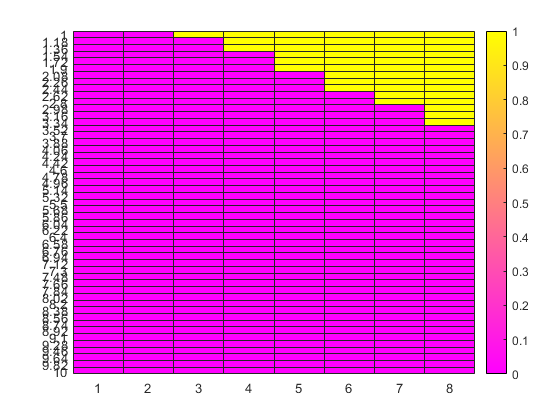

MinNumC = double(R <= Rth).*double(R > 0);
hm = heatmap(strtrim(cellstr(num2str(c'))'), ...
        strtrim(cellstr(num2str(L'))'), ...
        MinNumC, ...
        'Colormap', spring);